# MATLAB Tutorial 

Use MATLAB to complete the following problems. 

## Explore some basic functions of MATLAB. 

(a) Explain each of the following commands. 

(i) >> a = 9 

(ii) >> b = pi/6 

(iii) >> c = 5*sin(b) - sqrt(a) 

(iv) >> d = exp(2) 

(v) >> e = log(exp(1)) 

%% Project 1
% Tutorial
clear all
clc
close all
%% Question 1
% (a)
% (i) assign the scalar 9 to the variable a
a = 9;

% (ii) assign the approximate value of pi/6 to the variable b
b = pi/6

b = 0.5236


% (iii) assign the value of 5sin(pi/6)-sqrt(9) to the variable c
c = 5*sin(b)-sqrt(a)

c = -0.5000


% (iv) assign e^2 to the variable d
d = exp(2)

d = 7.3891


% (v) Assign the log of e to e
e = log(exp(1))

e = 1

(b) Plot the curve 𝑦 = 𝑥 3 + 𝑥 2 + 𝑥 + 1 on the interval [0,5]. 

(i) Define the function handle in MATLAB. 

>> f = @(x) x.^3 + x.^2 + x + 1; 

(ii) Pick discrete values of 𝑥 in [0,5] with step size 0.1. 

>> x = 0:0.1:5; 

(iii) Compute the corresponding 𝑦-values. 

>> y = f(x); 

(iv) Use the plot commands to draw the graph. 

>> plot(x,y); 

% (b)
% (i) Define the function_handle in MATLAB
f = @(x) x.^3 + x.^2 + x +1

f = function_handle with value:
    @(x)x.^3+x.^2+x+1



% (ii) Pick discrete values of x in [0,5];
x = 0:0.1:5

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


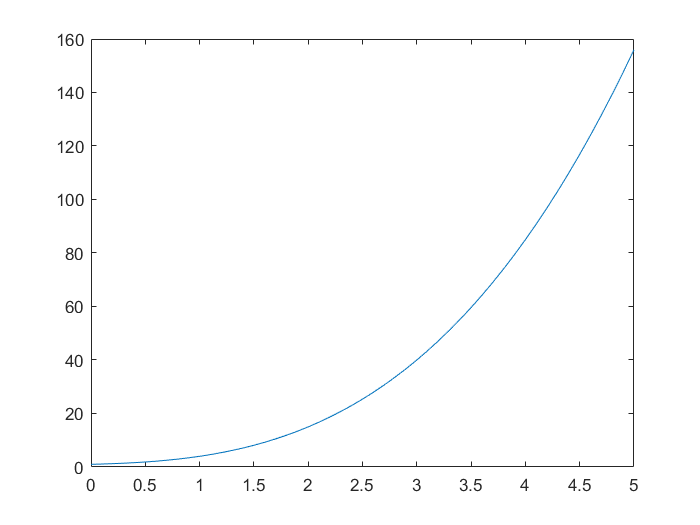


% (iii) Compute the corresponding y-values
y = f(x);

% (iv) Plot the graph
plot(x,y);
 hold on

(c) Modify the commands in (b) to plot the curve 𝑦 = 𝑒 𝑥 + 𝑥 cos 𝑥 on the interval [0,3].

 % (c) Modify the code above to plot the graph of f(x) = e^x+xcosx
% (i) Define the function_handle in MATLAB
f = @(x) exp(x) + x.*cos(x)

f = function_handle with value:
    @(x)exp(x)+x.*cos(x)



% (ii) Pick discrete values of x in [0,3];
x = 0:0.1:5

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


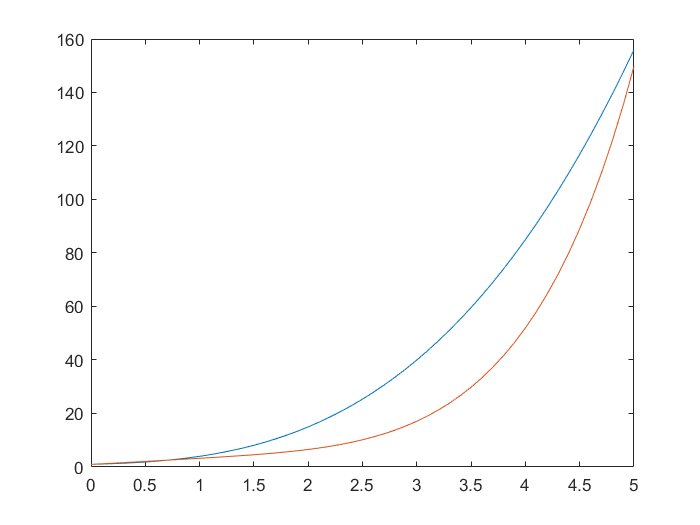


% (iii) Compute the corresponding y-values
y = f(x);

% (iv) Plot the graph
plot(x,y);
 hold off 

## Using Euler's Method

Consider the initial value problem 𝑑𝑦 𝑑𝑥 = 𝑥 + 𝑦, 𝑦(0) = 1. 

(a) Approximate the solution on [0,0.3] using Euler’s method with step  size ℎ = 0.1.  

(b) Use the MATLAB function ode45 to solve the IVP analytically. 

(c) Plot the analytic solution on the same graph as the approximate  solution. 

(d) Add a title and legend to the graph, and label the axes.

 %% Question 2
% Consider the IVP
yprime = @(x,y) x + y

yprime = function_handle with value:
    @(x,y)x+y


y0 = 1

y0 = 1


% (a) Approximate the solution on [0,0.3] using Euler's method.
[x, y_approx, ~, ytable] = eulers(yprime,0,0.3,y0,0.1)

x =                    0   0.100000000000000   0.200000000000000   0.300000000000000


y_approx =    1.000000000000000   1.100000000000000   1.220000000000000   1.362000000000000


ytable = 4×3 table
          x       y        f  
         ___    _____    _____

    0      0        1        1
    1    0.1      1.1      1.2
    2    0.2     1.22     1.42
    3    0.3    1.362    1.662


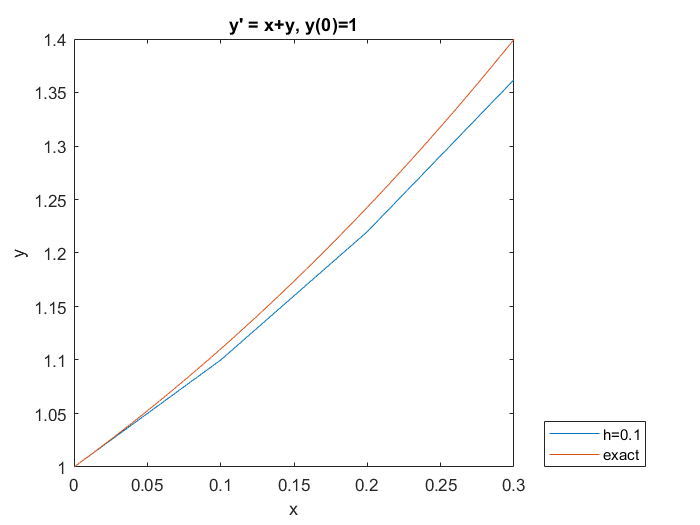


% (b) Solve the IVP
xspan = 0:0.0001:0.3;
[~, y_exact] = ode45(yprime,xspan,y0);

% (c)  Plot the solutions on the same graph
figure
plot(x,y_approx)
hold on
plot(xspan,y_exact)
hold off

% (c) Label the graph
title('y'' = x+y, y(0)=1')
legend('h=0.1', 'exact','Location','southeastoutside')
xlabel('x')
ylabel('y')

## Euler's Method

function [x y f table] = eulers(yprime,a,b,y0,h)
% Euler's method on [a,b]
% Author: Harrison Watts
% Date published: Dec. 18, 2021
% 
% y' = f(x,y), y(a)=y0
% yprime = @(x,y) function that describes y'
% a = x0, starting point for x
% b = endpoint of interval of evaluation
% y0 = starting point for y
% h = stepsize
% 
% x = x0 + nh
% y = solution values
% f = slopes at each iteration
% table = printed table of results
% 

% initial values
% x = a:h:b;
y = y0;
f = yprime(x(1),y(1));

% number of steps
N = size(x,2); %size(x,2) gives #columns in x
% start loop
for n=1:N-1

    % Euler's method 
    % y(n+1) = y(n) + h*f(x(n),y(n))
    y(n+1) = y(n)+h*f(n);

    % f(n+1) = f(x(n+1),y(n+1))
    f(n+1) = yprime(x(n+1),y(n+1));
end
    
% print results
format long
table_1 = [x; y; f]';
rowNames = arrayfun(@num2str,0:N-1,'Uni',0);
colNames = {'x','y','f'};
table = array2table(table_1,'RowNames',rowNames,'VariableNames',colNames);    
end